# Example: Solver for Acoustics in 2D with Multipole Sources

This live-script features the following:

- 2D example

- how to set up multipole sources

In 2D, mutipole sources are of the form


$$f(x,y,t) = \sum_{m=1}^M w_m(t) D^{\mathbf s_m}\delta(x-x_{m},y-y_m)$$


where 

- $w_m(t)$ is the time function of the $m$-th term

- $\mathbf s_m\in\mathbb N^2$ is the derivative order of the $m$-th term

- $D^{\mathbf s_m}\delta(x-x_m,y-y_m)$ is the $\mathbf s_m$-mixed derivative of the Dirac delta function shifted by $(x_m,y_m)$

- $(x_m,y_m)$ is the center/location of the $m$-th term

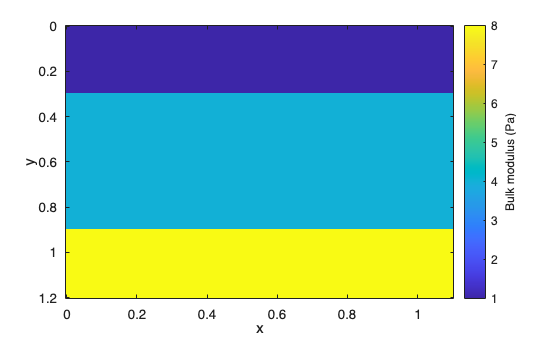

clear

domain_x = [0,1.1];
domain_y = [0,1.2];
domain_t = [0,1];

% Computational grids and grid spaces
Nx = 151;
Ny = 161; 
grid_x_primal = Grid1DUnifPrimal(domain_x,Nx);
grid_y_primal = Grid1DUnifPrimal(domain_y,Ny);
grid_x_dual   = Grid1DUnifDual(grid_x_primal);
grid_y_dual   = Grid1DUnifDual(grid_y_primal);
gsp_P  = GridSpace2D(grid_x_primal, grid_y_primal);
gsp_Vx = GridSpace2D(grid_x_dual,   grid_y_primal);
gsp_Vy = GridSpace2D(grid_x_primal, grid_y_dual);
h = gsp_P.h; %spatial grid sizes, h = [dx,dy]

% Acoustic medium parameters
medium = AcousticMedium2D.layeredY( ...
    BetaValues=[1,0.5,0.25], ...
    KappaValues=[1,4,8], ...
    Domain=[domain_x;domain_y], ...
    RelativeWidths=[0.25,0.5,0.25]);
[kappa,beta_x,beta_y,wspeed,cMax] = sampleMedium2D(gsp_P,medium);

kappa.plot;


% Time grid (computed after medium)
CFL_factor = 0.9;
dt = CFL_factor*(6/7)/(cMax*sqrt(sum(1./gsp_P.h.^2))); %CFL condition for 2-4 FDM
Nt = ceil(diff(domain_t)/dt)+1;
dt = diff(domain_t)/(Nt-1); %recomputing to ensure time domain divisible by dt
t_pts = domain_t(1):dt:domain_t(2);

% Output grid and times
gsp_out = GridSpace2D( ...
    Grid1DUnifPrimal(domain_x,101), ...
    Grid1DUnifPrimal(domain_x,101));
t_pts_out = linspace(domain_t(1),domain_t(2),81);

% Initial conditions
p0 = @(x,y) zeros(size(x));
vx0 = @(x,y) zeros(size(x));
vy0 = @(x,y) zeros(size(x));

% Initializing PML
pml = PML2D( ...
    WidthLeft=0.15, ...
    WidthRight=0.15, ...
    WidthBottom=0.15, ...
    WidthTop=0.15);

% Initializing solver
solver = AcousticSolver2D_PML( ...
    gsp_P,t_pts, ...
    gsp_out,t_pts_out, ...
    medium,pml, ...
    SpatialOrder=4);

Here we initialize several examples of multipole pressure sources.

Single term monopole: $f(x,y,t) = w_0(t)\delta(x-x_0,y-y_0)$

location0 = [0.35,0.45];
s0 = [0,0];
w0 = @(t) exp(-((t-0.10)/0.025).^2);
monopole = MultipoleTerm2D(location0,s0,w0,TargetField="pressure");

Single term dipole: $f(x,y,t) = w_1(t)D^{s_1}\delta(x-x_1,y-y_1)$.

For $s_1=(1,0)$, then $D^{s_1} = \frac{\partial}{\partial x}$.

Typically multipoles are scaled so that the results are comparable between different terms.

location1 = [0.65,0.55];
s1 = [1,0];
w1 = @(t) h(1)*10*exp(-((t-0.18)/0.035).^2);
dipoleX = MultipoleTerm2D(location1,s1,w1,TargetField="pressure");

Multipole series: $f(x,y,t) = w_0(t)\delta(x-x_0) + w_t(t)\delta'(x-x_1)$

mps_series = MultipoleSeries2D([monopole,dipoleX]);

To generate an acoustic source we apply the discretize method for multipoles.

Approximation order of multipole should match the spatial order of FDM.

src_monopole = monopole.discretize(gsp_P,gsp_Vx,gsp_Vy);
src_dipoleX = dipoleX.discretize(gsp_P,gsp_Vx,gsp_Vy);
src_series = mps_series.discretize(gsp_P,gsp_Vx,gsp_Vy);

% Run the solver
[P_monopole,~,~] = solver.solve(p0,vx0,vy0,Source=src_monopole);
[P_dipoleX,~,~] = solver.solve(p0,vx0,vy0,Source=src_dipoleX);
[P_series,~,~] = solver.solve(p0,vx0,vy0,Source=src_series);

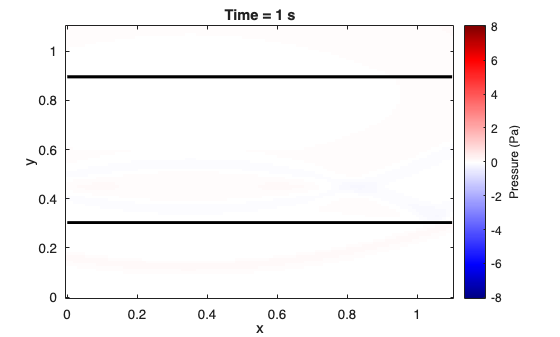

P_monopole.animateMedBack(medium);

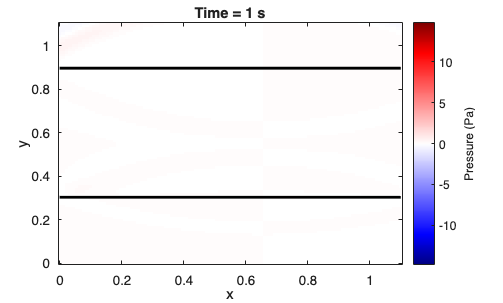

P_dipoleX.animateMedBack(medium);

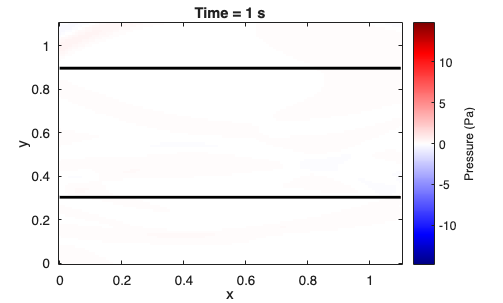

P_series.animateMedBack(medium);